img = imread("../resources/IMG_6759.jpg");
if size(img, 3) == 3
    gray_img = rgb2gray(img); % 转为灰度图像
else
    gray_img = img;
end

% 显示图像并让用户选择种子点
figure;
imshow(img);
title('请点击图像以选择种子点');
[x, y] = ginput(1); % 交互选择种子点
x = round(x);
y = round(y);

% 区域生长参数
seed = [y, x]; % 注意 MATLAB 图像坐标格式为 (行, 列)
threshold = 50; % 灰度值变化阈值，可根据需求调整

% 初始化区域生长
[rows, cols] = size(gray_img);
region = false(rows, cols);
region(seed(1), seed(2)) = true;
seed_gray_value = gray_img(seed(1), seed(2));

% 定义四邻域
neighbors = [-1 0; 1 0; 0 -1; 0 1];

% 区域生长算法
queue = seed; % 以队列形式存储待扩展像素
while ~isempty(queue)
    current_pixel = queue(1, :);
    queue(1, :) = []; % 出队列

    for k = 1:size(neighbors, 1)
        neighbor = current_pixel + neighbors(k, :);
        if neighbor(1) > 0 && neighbor(1) <= rows && neighbor(2) > 0 && neighbor(2) <= cols
            if ~region(neighbor(1), neighbor(2)) % 未访问过
                diff = abs(double(gray_img(neighbor(1), neighbor(2))) - double(seed_gray_value));
                if diff <= threshold
                    region(neighbor(1), neighbor(2)) = true;
                    queue = [queue; neighbor]; % 入队列
                end
            end
        end
    end
end

% 显示结果
shadow_mask = uint8(region) * 255; % 将逻辑矩阵转为图像格式
figure;
imshow(shadow_mask);
title('检测到的阴影区域');

clear;clc;
% 阴影检测 - 改进后的区域生长方法
% 结合局部特征（均值、方差、梯度、纹理）并引入动态阈值调整，解决暗区和亮区混淆问题

% 读取图像
img = imread("../resources/_MG_5844.jpg");
if size(img, 3) == 3
    gray_img = rgb2gray(img); % 转为灰度图像
else
    gray_img = img;
end

% 参数设置
window_size = 25; % 局部特征窗口大小，决定局部区域的大小
gradient_threshold = 0; % 梯度阈值，用于选择阴影边界
texture_threshold = 0; % 纹理特征的阈值，用于筛选可能的阴影区域
dynamic_threshold_factor = 0.5; % 动态阈值因子，根据局部灰度变化调整

% 计算局部均值和局部方差
local_mean = imfilter(gray_img, fspecial('average', window_size), 'replicate');
local_var = imfilter(gray_img.^2, fspecial('average', window_size), 'replicate') - local_mean.^2;

% 计算图像的梯度（Sobel算子）
[gradient_x, gradient_y] = imgradientxy(gray_img, 'sobel');
gradient_magnitude = sqrt(gradient_x.^2 + gradient_y.^2);

% 计算局部纹理特征：使用局部二值模式（LBP）
lbp_image = extractLBPFeatures(gray_img, 'CellSize', [window_size window_size]);

% 归一化纹理特征
lbp_image = mat2gray(lbp_image);

% 由于各矩阵大小可能不同，先调整它们的尺寸一致
% 将所有矩阵调整为与原图大小一致
local_mean = imresize(local_mean, [size(gray_img, 1), size(gray_img, 2)]);
local_var = imresize(local_var, [size(gray_img, 1), size(gray_img, 2)]);
gradient_magnitude = imresize(gradient_magnitude, [size(gray_img, 1), size(gray_img, 2)]);
lbp_image = imresize(lbp_image, [size(gray_img, 1), size(gray_img, 2)]);

% 计算综合评分：阴影区域通常具有低均值、低方差、大梯度和特殊的纹理模式
shadow_score = double(local_mean) .* (1 - double(local_var)) .* (double(gradient_magnitude) > gradient_threshold) .* (double(lbp_image) > texture_threshold);

% 显示评分图，帮助用户选择种子点
figure;
imshow(shadow_score, []);
title('阴影区域评分图');
colormap jet; % 使用颜色图来显示评分

% 用户通过图形界面选择多个种子点
disp('请点击图像选择多个种子点，按回车结束选择');
[x, y] = ginput; % 用户选择多个种子点
% 打印选择的种子点位置
disp('选择的种子点位置：');
disp([x, y]);
% 区域生长参数
[rows, cols] = size(gray_img);
region = false(rows, cols); % 用于存储阴影区域
neighbors = [-1 0; 1 0; 0 -1; 0 1]; % 四邻域

% 区域生长算法：从用户选择的多个种子点开始生长阴影区域
for i = 1:length(x)
    seed = [round(y(i)), round(x(i))]; % 注意MATLAB图像坐标格式为 (行, 列)
    
    % 初始化队列
    queue = seed;
    region(seed(1), seed(2)) = true;
    seed_gray_value = gray_img(seed(1), seed(2));
    
    % 动态阈值调整：根据种子点的局部特征调整阈值
    local_threshold = double(local_mean(seed(1), seed(2))) * dynamic_threshold_factor; % 基于种子点周围灰度的动态阈值

    % 区域生长过程
    while ~isempty(queue)
        current_pixel = queue(1, :);
        queue(1, :) = []; % 出队列

        for k = 1:size(neighbors, 1)
            neighbor = current_pixel + neighbors(k, :);
            if neighbor(1) > 0 && neighbor(1) <= rows && neighbor(2) > 0 && neighbor(2) <= cols
                if ~region(neighbor(1), neighbor(2)) % 未访问过
                    % 根据动态阈值判断是否加入区域
                    diff = abs(double(gray_img(neighbor(1), neighbor(2))) - double(seed_gray_value));
                    if diff <= local_threshold
                        region(neighbor(1), neighbor(2)) = true;
                        queue = [queue; neighbor]; % 入队列
                    end
                end
            end
        end
    end
end

% 阴影检测 - 闭运算提取阴影外边界并填充内部

% 生成阴影区域的掩模（假设你已经有了 'shadow_mask' 作为阴影区域的初步检测结果）
shadow_mask = uint8(region) * 255; % 如果你已经做了区域生长，shadow_mask 是阴影的掩模

% 定义结构元素（用来进行闭运算）
se = strel('disk', 5); % 'disk'是圆形结构元素，可以调整半径大小

% 闭运算：填充阴影区域内部
filled_shadow_mask = imclose(shadow_mask, se);

% 提取阴影区域的外边界
shadow_boundary = filled_shadow_mask - shadow_mask;

% 显示结果
figure;
subplot(1, 3, 1);
imshow(shadow_mask);
title('原始阴影区域');

subplot(1, 3, 2);
imshow(filled_shadow_mask);
title('闭运算填充后的阴影区域');

subplot(1, 3, 3);
imshow(shadow_boundary);
title('阴影外边界');


clear;clc;
% 阴影检测 - 智能辅助选择多个种子点
% 结合局部特征（均值、方差、梯度）来选择可能的阴影区域

% 读取图像
img = imread("../resources/_MG_6147.jpg");
if size(img, 3) == 3
    gray_img = rgb2gray(img); % 转为灰度图像
else
    gray_img = img;
end

% 参数设置
window_size = 15; % 局部特征窗口大小，决定局部区域的大小
gradient_threshold = 0; % 梯度阈值，用于选择阴影边界
texture_threshold = 0; % 纹理特征的阈值，用于筛选可能的阴影区域

% 计算局部均值和局部方差
local_mean = imfilter(gray_img, fspecial('average', window_size), 'replicate');
local_var = imfilter(gray_img.^2, fspecial('average', window_size), 'replicate') - local_mean.^2;

% 计算图像的梯度（Sobel算子）
[gradient_x, gradient_y] = imgradientxy(gray_img, 'sobel');
gradient_magnitude = sqrt(gradient_x.^2 + gradient_y.^2);

% 计算局部纹理特征：使用局部二值模式（LBP）
lbp_image = extractLBPFeatures(gray_img, 'CellSize', [window_size window_size]);

% 归一化纹理特征
lbp_image = mat2gray(lbp_image);

% 由于各矩阵大小可能不同，先调整它们的尺寸一致
% 将所有矩阵调整为与原图大小一致
local_mean = imresize(local_mean, [size(gray_img, 1), size(gray_img, 2)]);
local_var = imresize(local_var, [size(gray_img, 1), size(gray_img, 2)]);
gradient_magnitude = imresize(gradient_magnitude, [size(gray_img, 1), size(gray_img, 2)]);
lbp_image = imresize(lbp_image, [size(gray_img, 1), size(gray_img, 2)]);

% 计算综合评分：阴影区域通常具有低均值、低方差、大梯度和特殊的纹理模式
shadow_score = double(local_mean) .* (1 - double(local_var)) .* (double(gradient_magnitude) > gradient_threshold) .* (double(lbp_image) > texture_threshold);

% 显示评分图，帮助用户选择种子点
figure;
imshow(shadow_score, []);
title('阴影区域评分图');
colormap jet; % 使用颜色图来显示评分

% 用户通过图形界面选择多个种子点
disp('请点击图像选择多个种子点，按回车结束选择');
[x, y] = ginput; % 用户选择多个种子点
% 打印选择的种子点位置
disp('选择的种子点位置：');
disp([x, y]);
% 区域生长参数
threshold = 50; % 灰度值变化阈值，可根据需求调整
[rows, cols] = size(gray_img);
region = false(rows, cols); % 用于存储阴影区域
neighbors = [-1 0; 1 0; 0 -1; 0 1]; % 四邻域

% 区域生长算法：从用户选择的多个种子点开始生长阴影区域
for i = 1:length(x)
    seed = [round(y(i)), round(x(i))]; % 注意MATLAB图像坐标格式为 (行, 列)
    
    % 初始化队列
    queue = seed;
    region(seed(1), seed(2)) = true;
    seed_gray_value = gray_img(seed(1), seed(2));
    
    % 区域生长过程
    while ~isempty(queue)
        current_pixel = queue(1, :);
        queue(1, :) = []; % 出队列

        for k = 1:size(neighbors, 1)
            neighbor = current_pixel + neighbors(k, :);
            if neighbor(1) > 0 && neighbor(1) <= rows && neighbor(2) > 0 && neighbor(2) <= cols
                if ~region(neighbor(1), neighbor(2)) % 未访问过
                    diff = abs(double(gray_img(neighbor(1), neighbor(2))) - double(seed_gray_value));
                    if diff <= threshold
                        region(neighbor(1), neighbor(2)) = true;
                        queue = [queue; neighbor]; % 入队列
                    end
                end
            end
        end
    end
end

% 显示检测结果
shadow_mask = uint8(region) * 255; % 将逻辑矩阵转为图像格式
figure;
imshow(shadow_mask);
title('检测到的阴影区域');

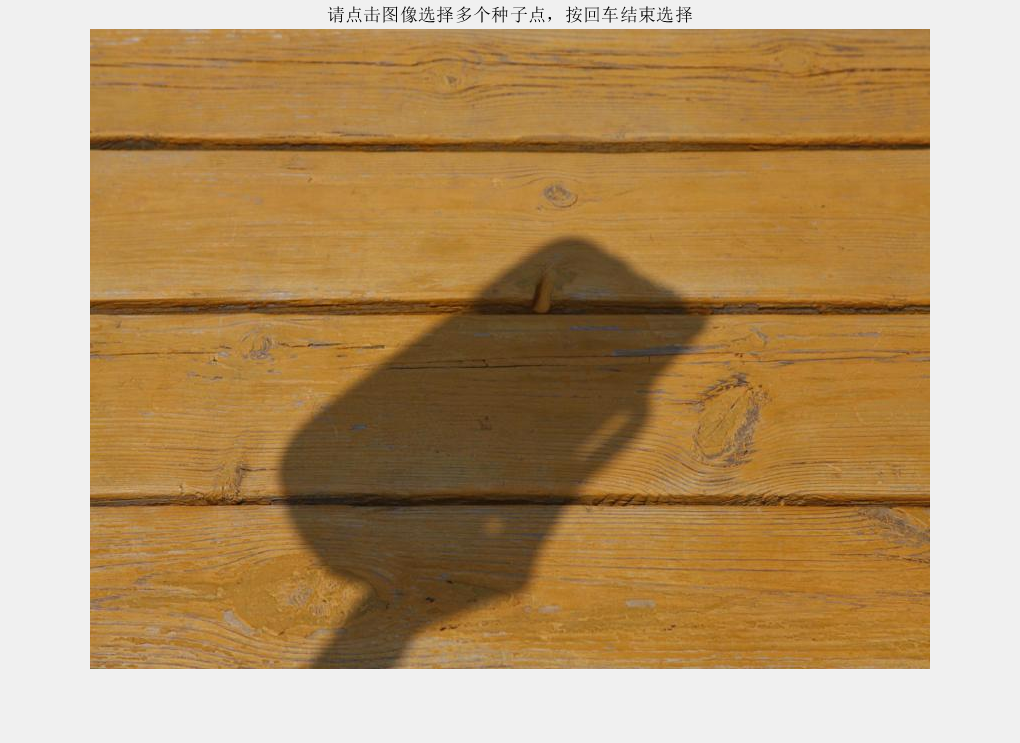

clear; clc;
% 阴影检测 - 区域生长法 (支持多个种子点)
% 允许用户选择多个种子点，结果取并集
% 目前在用的

% 读取图像
img = imread("../resources/_MG_6147.jpg");
if size(img, 3) == 3
    gray_img = rgb2gray(img); % 转为灰度图像
else
    gray_img = img;
end

% 显示图像并让用户选择多个种子点
figure;
imshow(img);
title('请点击图像选择多个种子点，按回车结束选择');
[x, y] = ginput; % 允许选择多个种子点

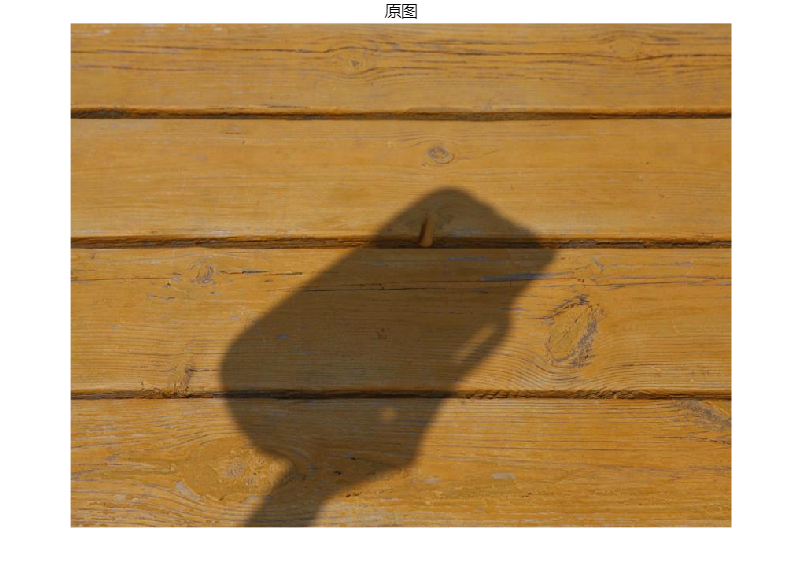

x = round(x);
y = round(y);

% 区域生长参数
threshold = 24; % 灰度值变化阈值，可根据需求调整

% 初始化区域生长
[rows, cols] = size(gray_img);
region = false(rows, cols); % 用于存储阴影区域

% 定义四邻域
neighbors = [-1 0; 1 0; 0 -1; 0 1];

% 区域生长算法函数
function region = grow_region(seed, gray_img, region, threshold, neighbors)
    [rows, cols] = size(gray_img);
    seed_gray_value = gray_img(seed(1), seed(2));
    
    % 初始化队列
    queue = seed;
    region(seed(1), seed(2)) = true;
    
    while ~isempty(queue)
        current_pixel = queue(1, :);
        queue(1, :) = []; % 出队列

        for k = 1:size(neighbors, 1)
            neighbor = current_pixel + neighbors(k, :);
            if neighbor(1) > 0 && neighbor(1) <= rows && neighbor(2) > 0 && neighbor(2) <= cols
                if ~region(neighbor(1), neighbor(2)) % 未访问过
                    diff = abs(double(gray_img(neighbor(1), neighbor(2))) - double(seed_gray_value));
                    if diff <= threshold
                        region(neighbor(1), neighbor(2)) = true;
                        queue = [queue; neighbor]; % 入队列
                    end
                end
            end
        end
    end
end

% 对每个种子点进行区域生长，取并集
for i = 1:length(x)
    seed = [y(i), x(i)]; % 注意 MATLAB 图像坐标格式为 (行, 列)
    region = grow_region(seed, gray_img, region, threshold, neighbors);
end

% 生成阴影区域的掩模（假设你已经有了 'shadow_mask' 作为阴影区域的初步检测结果）
shadow_mask = uint8(region) * 255; % 如果你已经做了区域生长，shadow_mask 是阴影的掩模

% 定义结构元素（用来进行闭运算）
se1 = strel('disk', 4); % 'disk'是圆形结构元素，可以调整半径大小
se2 = strel('disk', 3); % 'disk'是圆形结构元素，可以调整半径大小
% 闭运算：填充阴影区域内部
filled_shadow_mask = imclose(shadow_mask, se1);
% 开运算
erosed_shadow_mask = imopen(filled_shadow_mask, se2);
% 显示结果
figure;
imshow(img);
title('原图');

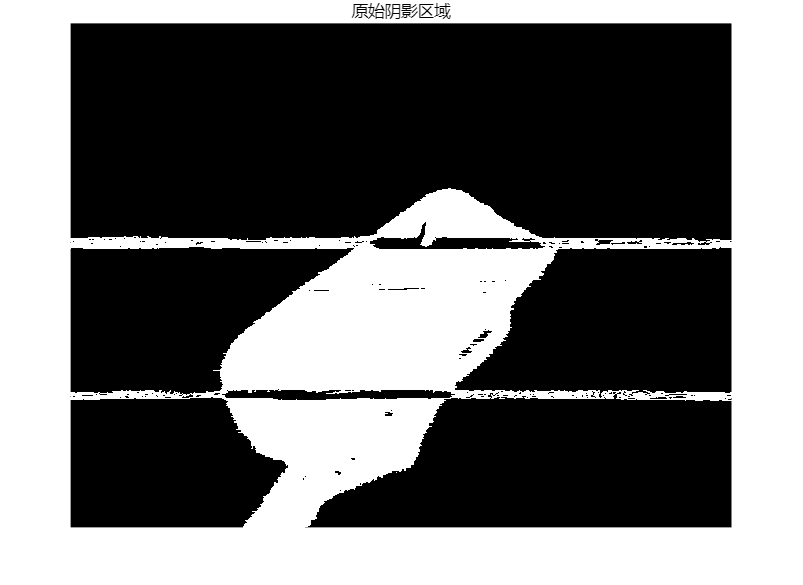

figure;
imshow(shadow_mask);
title('原始阴影区域');

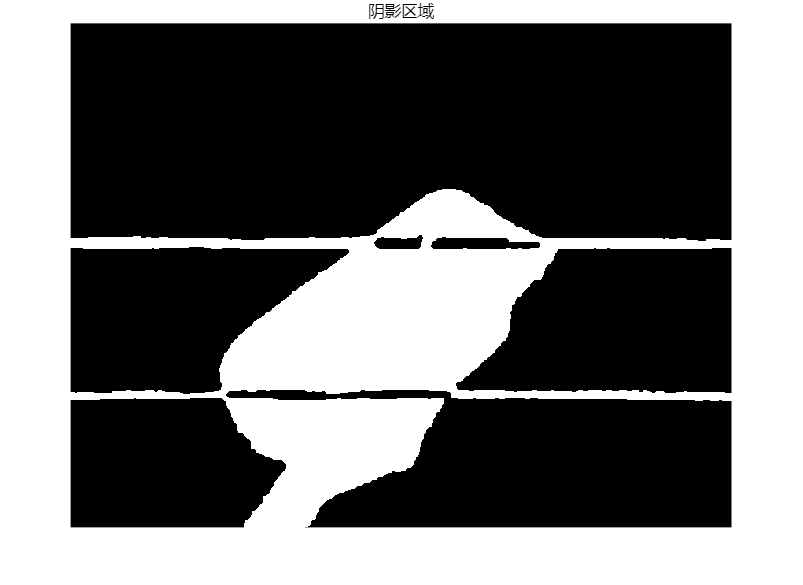

figure;
imshow(erosed_shadow_mask);
title('阴影区域');